1.	读取出MOD04_L2.A2017286.0315.006.2017286133610.hdf文件中的550nm 波段反演的 AOD 融合数据（产品名称：AOD_550_Dark_Target_Deep_Blue_Combined）以及对应的地理定位文件 Longitude 和 Latitude ：

clear;clc;
% 定义文件名
filename = "MOD04_L2.A2017286.0315.006.2017286133610.hdf";
% 查看文件信息
info = hdfinfo(filename,'eos');
% 输入swath name
swath_name = "mod04";
% 得到经度坐标
lon = hdfread(filename,swath_name,'Fields','Longitude');
% 得到纬度坐标
lat = hdfread(filename,swath_name,'Fields','Latitude');
% 得到AOD数据
AOD = hdfread(filename,"/AOD_550_Dark_Target_Deep_Blue_Combined");

% method1，从文件信息中得到数据属性，但是只能得到FillValue，不能得到scale_factor和add_offset
% 从文件信息中得到数据属性
DataFields = struct2table(info.Swath.DataFields);
% 从hdfinfo中得到FillValue
FillValue = DataFields.FillValue(find(DataFields.Name == "AOD_550_Dark_Target_Deep_Blue_Combined"));
% 从cell中得到FillValue的值
FillValue = FillValue{1};

% method2，使用HDF文件的基本I/O 方式来查找和读取FillValue, scale_factor和add_offset
% 加载matlab HDF4基础函数库
import matlab.io.hdf4.*
% 使用I/O方式打开文件
sdID = sd.start(filename);
% 获取指定数据集在HDF文件中的序号
idx = sd.nameToIndex(sdID,"AOD_550_Dark_Target_Deep_Blue_Combined");
% 获取该数据集的标识ID
sdsID = sd.select(sdID,idx);
% 提取FillValue
FillValue = sd.getFillValue(sdsID);
% 按照属性关键值查找
idx = sd.findAttr(sdsID,'scale_factor');
% 提取scale_factor属性值
scale_factor = sd.readAttr(sdsID,idx);
% 按照属性关键值查找
idx = sd.findAttr(sdsID,'add_offset');
% 提取add_offset属性值
offset = sd.readAttr(sdsID,idx);
% 结束数据集读取
sd.endAccess(sdsID);
% 结束文件读取
sd.close(sdID);
% 清除中间变量
clear sdID sdsID idx;

1. 将填充值（Fillvalue）替换为 NaN;

% 把AOD的类型从int转换成double
AOD = double(AOD);
% 将填充值（Fillvalue）替换为nan
AOD(AOD == FillValue) = nan;

2. 利用AOD_550_Dark_Target_Deep_Blue_Combined_QA_Flag 产品对 AOD 融合产品进行质量控制。

QA_Flag 为整型数字0~3，其中0=No Confidence, 1=Marginal, 2=Good，3=ver good。所以质量控制时只保留 Good 和 very good 的像元即可，将AOD 产品中其他 QA 对应的像元值全部替换为 NaN;

% 得到QA_Flag数据
QA_Flag = hdfread(filename,"/AOD_550_Dark_Target_Deep_Blue_Combined_QA_Flag");
% 把QA_Flag的类型从int转换成double
QA_Flag = double(QA_Flag);
% 将AOD 产品中对应QA<2的像元值全部替换为 NaN;
AOD(QA_Flag < 2) = nan;

3. 对质量控制后的AOD 数据产品进行定标（true_value=data_value*scale_factor+offset）

% 对质量控制后的AOD 数据产品进行定标
AOD_grids = AOD * scale_factor + offset;

4. 根据读取的经纬度数据的最小值和最大值，构建该AOD 产品的BoundingBox（为了便于可视化，常常将经纬度最小值减去5个像元大小，最大值加上5个像元大小(空间分辨率设为0.1°， 约12 km)，即范围扩大一圈，确保数据值能够显示完整）。根据 boundingbox 范围，建立标准的经纬度格网（经度范围：min_lon-5*0.1 ~ max_lon +5*0.1，纬度范围，min_lat-5 *0.1 ~ max_lat +5 *0.1 ），然后根据地理定位文件，将定标后的AOD数据进行投影转换，生成标准经纬度格网下的550 nm 波段反演的 AOD数据产品。

% 得到lat的最小值
minLat = min(lat,[],"all") - 5 * 0.1;
% 得到lon的最小值
minLon = min(lon,[],"all") - 5 * 0.1;
% 得到lat的最大值
maxLat = max(lat,[],"all") + 5 * 0.1;
% 得到lon的最大值
maxLon = max(lon,[],"all") + 5 * 0.1;
% 得到数据大小
rasterSize = size(lat);
% 建立空间几何校正映射数组R
R = georefcells(double([minLat maxLat]), double([minLon maxLon]), rasterSize);
% 经纬度转换为行列号
[xIntrinsic,yIntrinsic] = geographicToIntrinsic(R,lat,lon);

5. 图形显示输出格网化 AOD 数据：假定格网化数据为 AOD_grids。可视化语句如下：pcolor(x, y, AOD_grids); shading flat; colormap(jet)；colorbar

其中，x 和 y 分别对应 AOD_grids的经度和纬度，请自行根据第4步中的经纬度范围创建。将输出的图像截屏后粘贴在代码后。

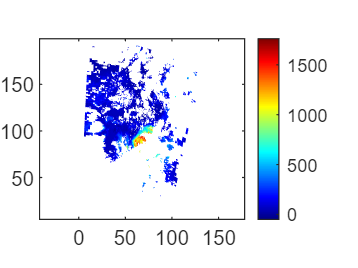

% 制图
pcolor(xIntrinsic, yIntrinsic, AOD); shading flat; colormap(jet); colorbar; axis equal;